cd('/Volumes/PcSSDA/1626/20220313_1626_SW_002')
load('FLP_analysis_0426.mat')
ExperimentName='20220313_1626_SW_002'; % Give a specific name to this experiment or this analysis
FirstAcq=10; % What's the acquisition number of the first offical recording
number_of_acq = 24; % How many chunks of recordings are there?
Dark_hours=[11 12 13 14 15 16 17 18 19 20 21 22 23]

Dark_hours =     11    12    13    14    15    16    17    18    19    20    21    22    23


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 



analysis_name=[ExperimentName,'_analysis_'];
FLPfiles='continuous aquistion data_'; 
starting_reference_file=dir([ExperimentName,'FLIM001.mat'])

starting_reference_file = struct with fields:
       name: '20220313_1626_SW_002FLIM001.mat'
     folder: '/Volumes/PcSSDA/1626/20220313_1626_SW_002'
       date: '13-Mar-2022 16:34:48'
      bytes: 2982
      isdir: 0
    datenum: 7.3859e+05


starting_reference_time=datetime(starting_reference_file.date);
SixClockNorm=datetime(starting_reference_time.Year,starting_reference_time.Month, starting_reference_time.Day,18,0,0);

EEGdata_all=[];
EMGdata_all=[];
EEGtime_all=[];
EMGtime_all=[];

EEGtime=1/200:1/200:3600;
EMGtime=1/400:1/400:3600;

for i=1:size(Dark_hours,2)
    EEGfile=['extracted_data/downsampEEG_Acq',num2str(Dark_hours(i)),'.npy'];
    EEGdata=readNPY(EEGfile);
    EEGdata_all=[EEGdata_all; EEGdata];

    EMGfile=['AD3_',num2str(Dark_hours(i)),'.mat'];
    load(EMGfile);
    eval(['EMGdata=AD3_',num2str(Dark_hours(i)),'.data;'])
    EMGdata_all=[EMGdata_all EMGdata];

    rawfile=dir(['AD3_',num2str(Dark_hours(i)),'.mat']);
    reference_time=datetime(rawfile.date);
    time_z_EEG=seconds(reference_time-SixClockNorm)+(EEGtime-max(EEGtime));
    time_z_EMG=seconds(reference_time-SixClockNorm)+(EMGtime-max(EMGtime));
    
    EEGtime_all=[EEGtime_all time_z_EEG];
    EMGtime_all=[EMGtime_all time_z_EMG];

end

Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...



EEGdarks=find(EEGtime_all>=0 & EEGtime_all<=43200);
EMGdarks=find(EMGtime_all>=0 & EMGtime_all<=43200);

EEGtimedark=EEGtime_all(EEGdarks);
EMGtimedark=EMGtime_all(EMGdarks);
EEGdata_all_dark=EEGdata_all(EEGdarks);
EMGdata_all_dark=EMGdata_all(EMGdarks);

    



outlier1=[];
outlier2=[];
outlier3=[];
outlier4=[];


t=time_z_all_darkonly;
state1epochs=readNPY('state1test.npy');
state2epochs=readNPY('state2test.npy');
state3epochs=readNPY('state3test.npy');
state4epochs=readNPY('state4test.npy');

state1epochs=state1epochs+1;
state2epochs=state2epochs+1;
state3epochs=state3epochs+1;
state4epochs=state4epochs+1;


median_time_1=[];
median_1=[];
median_time_1out=[];
median_1out=[];
epoch_length_1=[];

for i=1:size(state1epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state1epochs(i,1):state1epochs(i,2));
    this_epoch_length=t(state1epochs(i,2))-t(state1epochs(i,1));
    median_1=[median_1 median(this_epoch)];
    epoch_length_1=[epoch_length_1 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state1epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state1epochs(i,1))-1;
    end
    
    median_time_1=[median_time_1 this_median];

    if isempty(find(outlier1==i))==0
        median_time_1out=[median_time_1out this_median];
        median_1out=[median_1out median(this_epoch)];
    end
end

median_time_2=[];
median_2=[];
median_time_2out=[];
median_2out=[];
epoch_length_2=[];

for i=1:size(state2epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state2epochs(i,1):state2epochs(i,2));
    this_epoch_length=t(state2epochs(i,2))-t(state2epochs(i,1));
    median_2=[median_2 median(this_epoch)];
    epoch_length_2=[epoch_length_2 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state2epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state2epochs(i,1))-1;
    end
    
    median_time_2=[median_time_2 this_median];
    if isempty(find(outlier2==i))==0
        median_time_2out=[median_time_2out this_median];
        median_2out=[median_2out median(this_epoch)];
    end
end

median_time_3=[];
median_3=[];
median_time_3out=[];
median_3out=[];
epoch_length_3=[];

for i=1:size(state3epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state3epochs(i,1):state3epochs(i,2));
    this_epoch_length=t(state3epochs(i,2))-t(state3epochs(i,1));
    median_3=[median_3 median(this_epoch)];
    epoch_length_3=[epoch_length_3 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state3epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state3epochs(i,1))-1;
    end
    
    median_time_3=[median_time_3 this_median];
    if isempty(find(outlier3==i))==0
        median_time_3out=[median_time_3out this_median];
        median_3out=[median_3out median(this_epoch)];
    end
end

median_time_4=[];
median_4=[];
median_time_4out=[];
median_4out=[];
epoch_length_4=[];

for i=1:size(state4epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state4epochs(i,1):state4epochs(i,2));
    this_epoch_length=t(state4epochs(i,2))-t(state4epochs(i,1));
    median_4=[median_4 median(this_epoch)];
    epoch_length_4=[epoch_length_4 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state4epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state4epochs(i,1))-1;
    end
    
    median_time_4=[median_time_4 this_median];
    if isempty(find(outlier4==i))==0
        median_time_4out=[median_time_4out this_median];
        median_4out=[median_4out median(this_epoch)];
    end
end

save('median_information.mat','median_time_1','median_time_2','median_time_3','median_time_4','time_z_all_darkonly','tau_empTrunc_all_darkonly','intensity_all_darkonly')


t=time_z_all_darkonly;
t1=t(median_time_1);
t2=t(median_time_2);
t3=t(median_time_3);
t4=t(median_time_4);

t1out=t(median_time_1out)


t1out =

     []



t2out=t(median_time_2out)


t2out =

     []



t3out=t(median_time_3out)


t3out =

     []



t4out=t(median_time_4out)


t4out =

     []



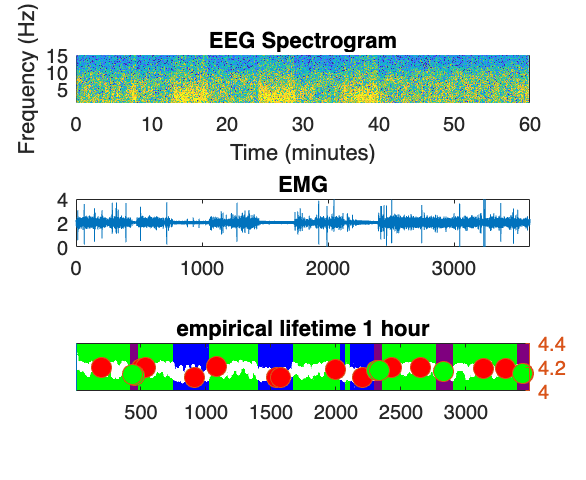

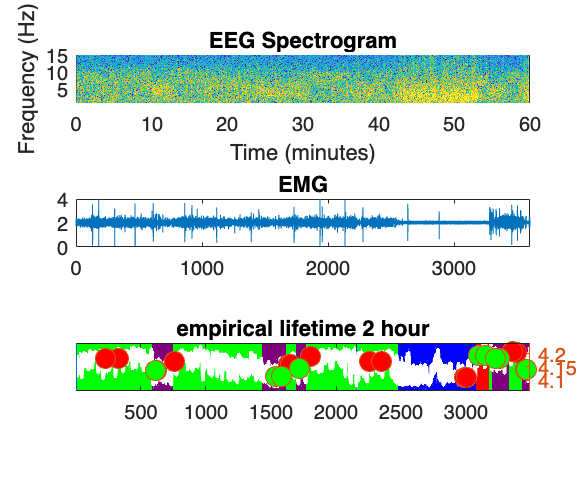

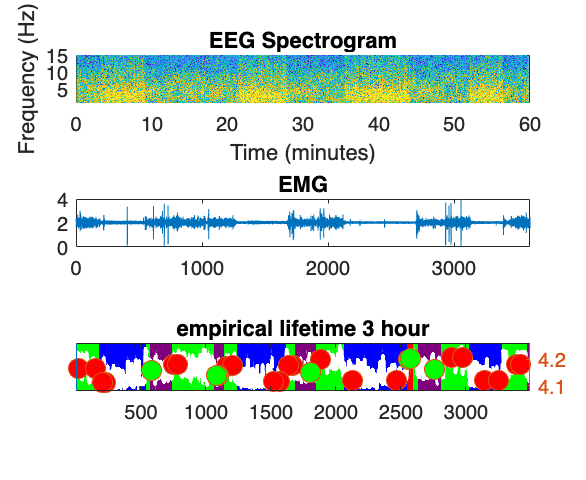

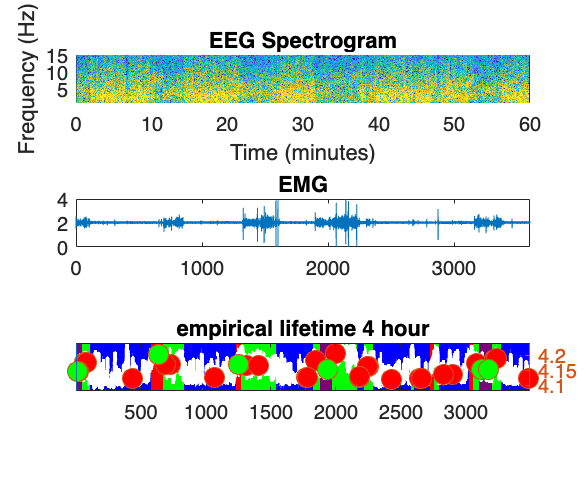

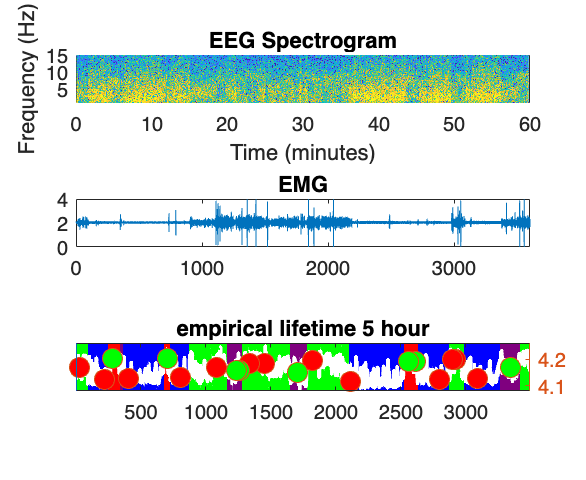

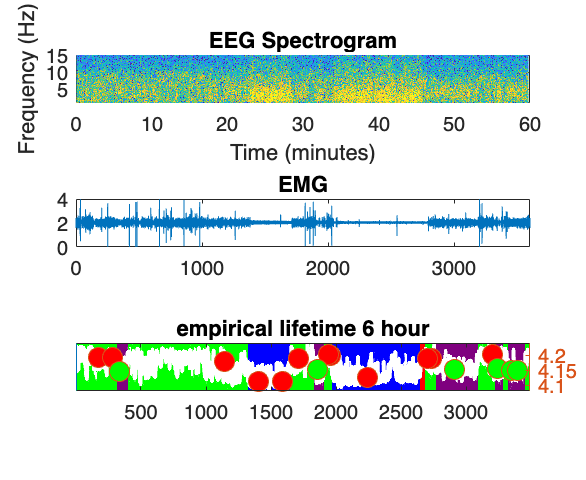

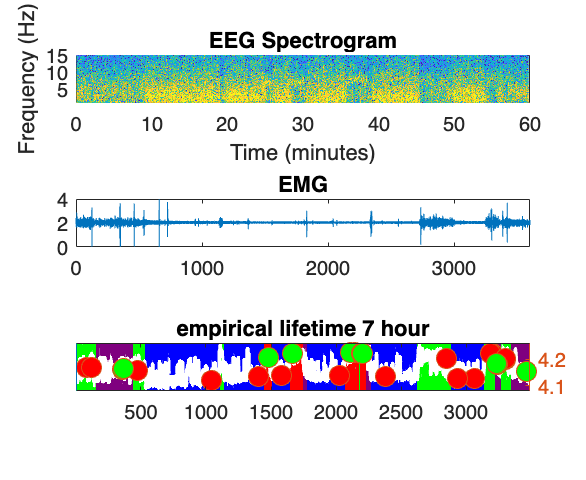

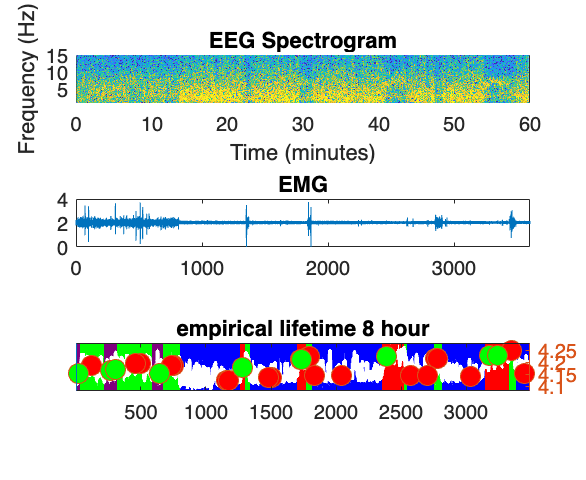


Fs = 200; % 
tWindow = 10; % The window must be long enough to get 64ms of the signal
NWindow = Fs*tWindow; % Number of elements the window must have
window = hamming(NWindow); % Window used in the spectrogram
NFFT = NWindow;
NOverlap = NWindow*0.99; % We want a 99% overlap,

for i=1:12
    this_plot_points=find(t>=3600*(i-1) & t<=3600*i);
    this_plot_points_EEG=find(EEGtimedark>=3600*(i-1) & EEGtimedark<=3600*i);
    this_plot_points_EMG=find(EMGtimedark>=3600*(i-1) & EMGtimedark<=3600*i);
    EMGtime_plot=EMGtimedark(this_plot_points_EMG);
    EMGtime_plot=EMGtime_plot-EMGtime_plot(1);

    this_plot_median_points_1=median_time_1(find(t1>=3600*(i-1) & t1<=3600*i));
    this_plot_median_points_2=median_time_2(find(t2>=3600*(i-1) & t2<=3600*i));
    this_plot_median_points_3=median_time_3(find(t3>=3600*(i-1) & t3<=3600*i));
    this_plot_median_points_4=median_time_4(find(t4>=3600*(i-1) & t4<=3600*i));

    this_plot_median_points_1out=median_time_1out(find(t1out>=3600*(i-1) & t1out<=3600*i));
    this_plot_median_points_2out=median_time_2out(find(t2out>=3600*(i-1) & t2out<=3600*i));
    this_plot_median_points_3out=median_time_3out(find(t3out>=3600*(i-1) & t3out<=3600*i));
    this_plot_median_points_4out=median_time_4out(find(t4out>=3600*(i-1) & t4out<=3600*i));
    
    figure1=figure;
    figure1.Position=[10 10 1100 900];

    subplot1=subplot(3,1,1,'Parent',figure1);
    hold(subplot1,'on')
    spectrogram(EEGdata_all_dark(this_plot_points_EEG), window, NOverlap, NFFT, Fs,'yaxis');
    ylim([1,15])
    caxis([-40 -10])
    colorbar('off')
    box(subplot1,'on')
    title('EEG Spectrogram')
    hold(subplot1,'off')

    subplot2=subplot(3,1,2,'Parent',figure1);
    hold(subplot2,'on')
    plot(EMGtime_plot,EMGdata_all_dark(this_plot_points_EMG))
    xlim([0 3600])
    box(subplot2,'on')
    title('EMG')
    hold(subplot2,'off')

    subplot3=subplot(3,1,3,'Parent',figure1);
    yyaxis left
    imagesc(states_for_time_all_dark(this_plot_points)')
    caxis([1 4])
    colormap(subplot3,[0 1 0;0 0 1;1 0 0;.5 0 .5])
    colorbar('off')
    set(gca, 'YTick', []);
    title(['empirical lifetime ',num2str(i),' hour' ])
    
    yyaxis right
    plot(tau_empTrunc_all_darkonly(this_plot_points),'LineWidth',2,'Color','white')
    
    
    hold(subplot3,'on')
    yyaxis right
    plot(this_plot_median_points_1-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_1)','o','MarkerSize',10,'MarkerFaceColor','Red')
    plot(this_plot_median_points_2-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_2)','o','MarkerSize',10,'MarkerFaceColor','Red')
    plot(this_plot_median_points_3-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_3)','o','MarkerSize',10,'MarkerFaceColor','Green')
    plot(this_plot_median_points_4-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_4)','o','MarkerSize',10,'MarkerFaceColor','Green')

    plot(this_plot_median_points_1out-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_1out)','o','MarkerSize',10,'MarkerFaceColor','Black')
    plot(this_plot_median_points_2out-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_2out)','o','MarkerSize',10,'MarkerFaceColor','Black')
    plot(this_plot_median_points_3out-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_3out)','o','MarkerSize',10,'MarkerFaceColor','Black')
    plot(this_plot_median_points_4out-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_4out)','o','MarkerSize',10,'MarkerFaceColor','Black')
    hold(subplot3,'off')
    
    figurename=['median_ploted_',num2str(i),'.png'];
    saveas(figure1, figurename)
    
    
    
    
    
end

cd('/Volumes/PcSSDA/1626/20220318_1626_SW_003')
load('FLP_analysis_0426.mat')
ExperimentName='20220318_1626_SW_003'; % Give a specific name to this experiment or this analysis
FirstAcq=7; % What's the acquisition number of the first offical recording
number_of_acq = 22; % How many chunks of recordings are there?
Dark_hours=[7 8 9 10 11 12 13 14 15 16 17 18]

Dark_hours =      7     8     9    10    11    12    13    14    15    16    17    18


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

outlier1=[33 22 27];
outlier2=[20];
outlier3=[1 2 3];
outlier4=[24 25 16 19 18];

analysis_name=[ExperimentName,'_analysis_'];
FLPfiles='continuous aquistion data_'; 
starting_reference_file=dir([ExperimentName,'FLIM001.mat'])

starting_reference_file = struct with fields:
       name: '20220318_1626_SW_003FLIM001.mat'
     folder: '/Volumes/PcSSDA/1626/20220318_1626_SW_003'
       date: '18-Mar-2022 18:49:20'
      bytes: 2880
      isdir: 0
    datenum: 7.3860e+05


starting_reference_time=datetime(starting_reference_file.date);
SixClockNorm=datetime(starting_reference_time.Year,starting_reference_time.Month, starting_reference_time.Day,18,0,0);

EEGdata_all=[];
EMGdata_all=[];
EEGtime_all=[];
EMGtime_all=[];

EEGtime=1/200:1/200:3600;
EMGtime=1/400:1/400:3600;

for i=1:size(Dark_hours,2)
    EEGfile=['extracted_data/downsampEEG_Acq',num2str(Dark_hours(i)),'.npy'];
    EEGdata=readNPY(EEGfile);
    EEGdata_all=[EEGdata_all; EEGdata];

    EMGfile=['AD3_',num2str(Dark_hours(i)),'.mat'];
    load(EMGfile);
    eval(['EMGdata=AD3_',num2str(Dark_hours(i)),'.data;'])
    EMGdata_all=[EMGdata_all EMGdata];

    rawfile=dir(['AD3_',num2str(Dark_hours(i)),'.mat']);
    reference_time=datetime(rawfile.date);
    time_z_EEG=seconds(reference_time-SixClockNorm)+(EEGtime-max(EEGtime));
    time_z_EMG=seconds(reference_time-SixClockNorm)+(EMGtime-max(EMGtime));
    
    EEGtime_all=[EEGtime_all time_z_EEG];
    EMGtime_all=[EMGtime_all time_z_EMG];

end

Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...



EEGdarks=find(EEGtime_all>=0 & EEGtime_all<=43200);
EMGdarks=find(EMGtime_all>=0 & EMGtime_all<=43200);

EEGtimedark=EEGtime_all(EEGdarks);
EMGtimedark=EMGtime_all(EMGdarks);
EEGdata_all_dark=EEGdata_all(EEGdarks);
EMGdata_all_dark=EMGdata_all(EMGdarks);

    

t=time_z_all_darkonly;
state1epochs=readNPY('state1test.npy');
state2epochs=readNPY('state2test.npy');
state3epochs=readNPY('state3test.npy');
state4epochs=readNPY('state4test.npy');

state1epochs=state1epochs+1;
state2epochs=state2epochs+1;
state3epochs=state3epochs+1;
state4epochs=state4epochs+1;


median_time_1=[];
median_1=[];
median_time_1out=[];
median_1out=[];
epoch_length_1=[];

for i=1:size(state1epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state1epochs(i,1):state1epochs(i,2));
    this_epoch_length=t(state1epochs(i,2))-t(state1epochs(i,1));
    median_1=[median_1 median(this_epoch)];
    epoch_length_1=[epoch_length_1 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state1epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state1epochs(i,1))-1;
    end
    
    median_time_1=[median_time_1 this_median];

    if isempty(find(outlier1==i))==0
        median_time_1out=[median_time_1out this_median];
        median_1out=[median_1out median(this_epoch)];
    end
end

median_time_2=[];
median_2=[];
median_time_2out=[];
median_2out=[];
epoch_length_2=[];

for i=1:size(state2epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state2epochs(i,1):state2epochs(i,2));
    this_epoch_length=t(state2epochs(i,2))-t(state2epochs(i,1));
    median_2=[median_2 median(this_epoch)];
    epoch_length_2=[epoch_length_2 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state2epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state2epochs(i,1))-1;
    end
    
    median_time_2=[median_time_2 this_median];
    if isempty(find(outlier2==i))==0
        median_time_2out=[median_time_2out this_median];
        median_2out=[median_2out median(this_epoch)];
    end
end

median_time_3=[];
median_3=[];
median_time_3out=[];
median_3out=[];
epoch_length_3=[];

for i=1:size(state3epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state3epochs(i,1):state3epochs(i,2));
    this_epoch_length=t(state3epochs(i,2))-t(state3epochs(i,1));
    median_3=[median_3 median(this_epoch)];
    epoch_length_3=[epoch_length_3 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state3epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state3epochs(i,1))-1;
    end
    
    median_time_3=[median_time_3 this_median];
    if isempty(find(outlier3==i))==0
        median_time_3out=[median_time_3out this_median];
        median_3out=[median_3out median(this_epoch)];
    end
end

median_time_4=[];
median_4=[];
median_time_4out=[];
median_4out=[];
epoch_length_4=[];

for i=1:size(state4epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state4epochs(i,1):state4epochs(i,2));
    this_epoch_length=t(state4epochs(i,2))-t(state4epochs(i,1));
    median_4=[median_4 median(this_epoch)];
    epoch_length_4=[epoch_length_4 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state4epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state4epochs(i,1))-1;
    end
    
    median_time_4=[median_time_4 this_median];
    if isempty(find(outlier4==i))==0
        median_time_4out=[median_time_4out this_median];
        median_4out=[median_4out median(this_epoch)];
    end
end

save('median_information.mat','median_time_1','median_time_2','median_time_3','median_time_4','time_z_all_darkonly','tau_empTrunc_all_darkonly','intensity_all_darkonly')


t=time_z_all_darkonly;
t1=t(median_time_1);
t2=t(median_time_2);
t3=t(median_time_3);
t4=t(median_time_4);

t1out=t(median_time_1out)

t1out = 	1.0e+04 *

   2.584808000000000
   2.592360000000001
   3.019117999999999
   3.784551699999999
   3.780703700000000


t2out=t(median_time_2out)

t2out =      3.766979700000001e+04


t3out=t(median_time_3out)

t3out = 	1.0e+04 *

   0.711958100000001
   1.420309900000000
   1.421858000000000
   2.355832100000000
   2.349072000000000


t4out=t(median_time_4out)

t4out = 	1.0e+04 *

   2.601948100000000
   2.977236000000000
   3.027706000000000
   3.023470000000000
   3.712607799999999
   3.797765800000000


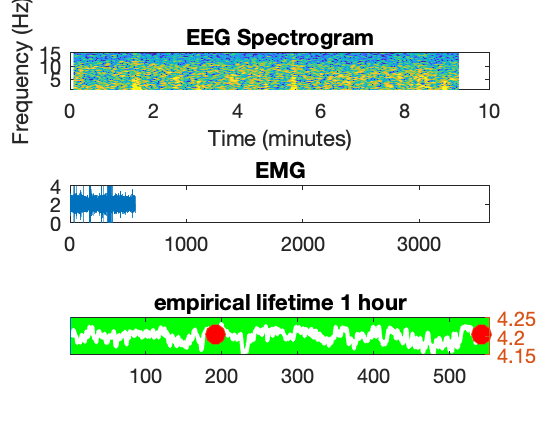

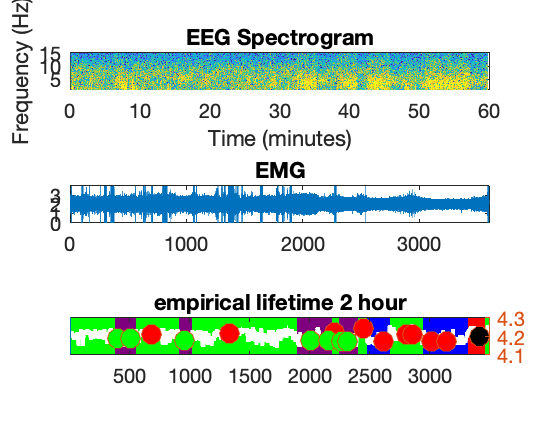

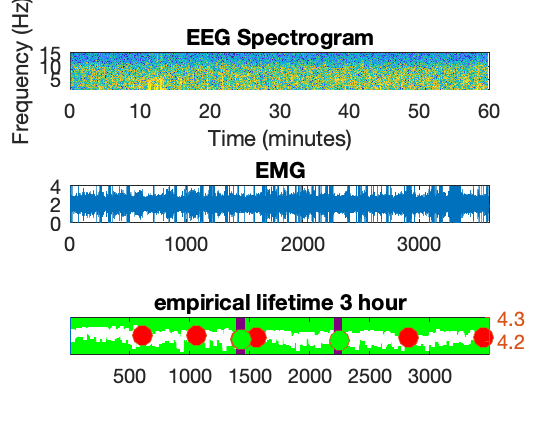

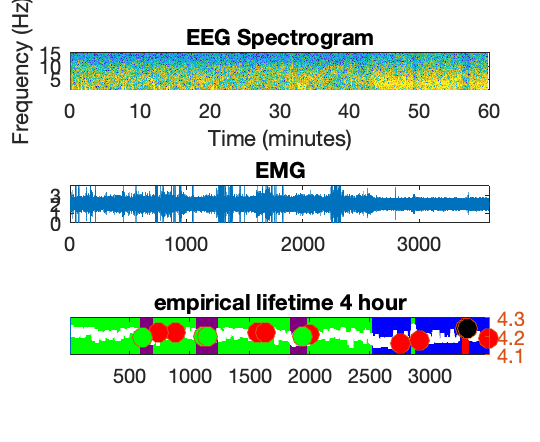

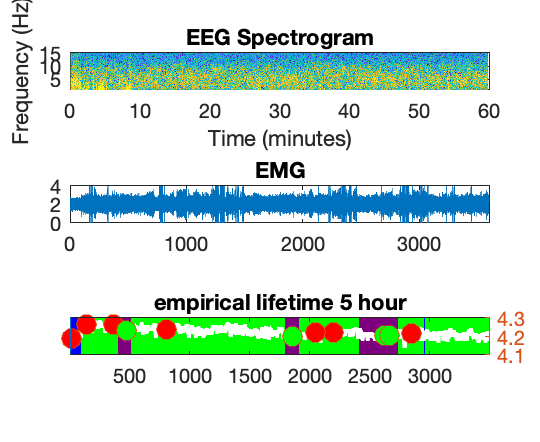

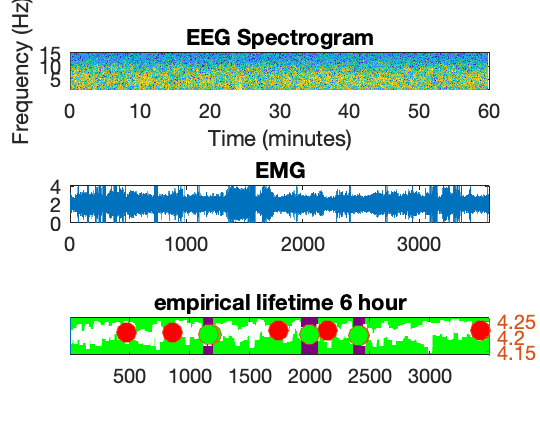

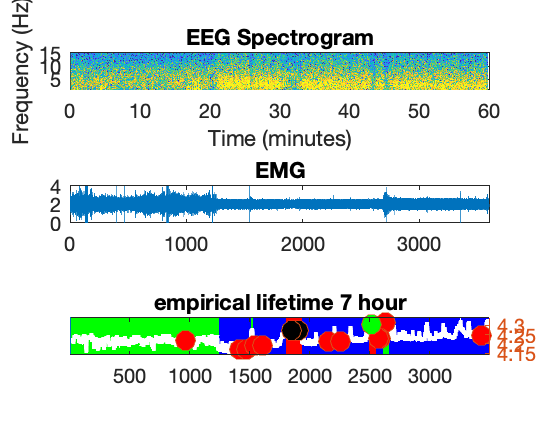

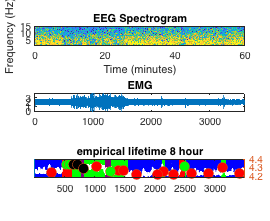


Fs = 200; % 
tWindow = 10; % The window must be long enough to get 64ms of the signal
NWindow = Fs*tWindow; % Number of elements the window must have
window = hamming(NWindow); % Window used in the spectrogram
NFFT = NWindow;
NOverlap = NWindow*0.99; % We want a 99% overlap,

for i=1:12
    this_plot_points=find(t>=3600*(i-1) & t<=3600*i);
    this_plot_points_EEG=find(EEGtimedark>=3600*(i-1) & EEGtimedark<=3600*i);
    this_plot_points_EMG=find(EMGtimedark>=3600*(i-1) & EMGtimedark<=3600*i);
    EMGtime_plot=EMGtimedark(this_plot_points_EMG);
    EMGtime_plot=EMGtime_plot-EMGtime_plot(1);

    this_plot_median_points_1=median_time_1(find(t1>=3600*(i-1) & t1<=3600*i));
    this_plot_median_points_2=median_time_2(find(t2>=3600*(i-1) & t2<=3600*i));
    this_plot_median_points_3=median_time_3(find(t3>=3600*(i-1) & t3<=3600*i));
    this_plot_median_points_4=median_time_4(find(t4>=3600*(i-1) & t4<=3600*i));

    this_plot_median_points_1out=median_time_1out(find(t1out>=3600*(i-1) & t1out<=3600*i));
    this_plot_median_points_2out=median_time_2out(find(t2out>=3600*(i-1) & t2out<=3600*i));
    this_plot_median_points_3out=median_time_3out(find(t3out>=3600*(i-1) & t3out<=3600*i));
    this_plot_median_points_4out=median_time_4out(find(t4out>=3600*(i-1) & t4out<=3600*i));
    
    figure1=figure;
    figure1.Position=[10 10 1100 900];

    subplot1=subplot(3,1,1,'Parent',figure1);
    hold(subplot1,'on')
    spectrogram(EEGdata_all_dark(this_plot_points_EEG), window, NOverlap, NFFT, Fs,'yaxis');
    ylim([1,15])
    caxis([-40 -10])
    colorbar('off')
    box(subplot1,'on')
    title('EEG Spectrogram')
    hold(subplot1,'off')

    subplot2=subplot(3,1,2,'Parent',figure1);
    hold(subplot2,'on')
    plot(EMGtime_plot,EMGdata_all_dark(this_plot_points_EMG))
    xlim([0 3600])
    box(subplot2,'on')
    title('EMG')
    hold(subplot2,'off')

    subplot3=subplot(3,1,3,'Parent',figure1);
    yyaxis left
    imagesc(states_for_time_all_dark(this_plot_points)')
    caxis([1 4])
    colormap(subplot3,[0 1 0;0 0 1;1 0 0;.5 0 .5])
    colorbar('off')
    set(gca, 'YTick', []);
    title(['empirical lifetime ',num2str(i),' hour' ])
    
    yyaxis right
    plot(tau_empTrunc_all_darkonly(this_plot_points),'LineWidth',2,'Color','white')
    
    
    hold(subplot3,'on')
    yyaxis right
    plot(this_plot_median_points_1-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_1)','o','MarkerSize',10,'MarkerFaceColor','Red')
    plot(this_plot_median_points_2-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_2)','o','MarkerSize',10,'MarkerFaceColor','Red')
    plot(this_plot_median_points_3-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_3)','o','MarkerSize',10,'MarkerFaceColor','Green')
    plot(this_plot_median_points_4-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_4)','o','MarkerSize',10,'MarkerFaceColor','Green')

    plot(this_plot_median_points_1out-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_1out)','o','MarkerSize',10,'MarkerFaceColor','Black')
    plot(this_plot_median_points_2out-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_2out)','o','MarkerSize',10,'MarkerFaceColor','Black')
    plot(this_plot_median_points_3out-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_3out)','o','MarkerSize',10,'MarkerFaceColor','Black')
    plot(this_plot_median_points_4out-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_4out)','o','MarkerSize',10,'MarkerFaceColor','Black')
    hold(subplot3,'off')
    
    figurename=['median_ploted_',num2str(i),'.png'];
    saveas(figure1, figurename)
    
    
    
    
    
end

cd('/Volumes/PcSSDA/1626/20220329_1626_SW_004')
load('FLP_analysis_0426.mat')
ExperimentName='20220329_1626_SW_004'; % Give a specific name to this experiment or this analysis
FirstAcq=10; % What's the acquisition number of the first offical recording
number_of_acq = 17; % How many chunks of recordings are there?
Dark_hours=[10 11 12 13 14 15 16 17 18 19 20 21 22]

Dark_hours =     10    11    12    13    14    15    16    17    18    19    20    21    22


darktime_calc = 0; % 0 or 1, determining different method to calculate dark time

analysis_name=[ExperimentName,'_analysis_'];
timebin=1;
ch=1;
FLPfiles='continuous aquistion data_'; 

outlier1=[];
outlier2=[];
outlier3=[];
outlier4=[];

analysis_name=[ExperimentName,'_analysis_'];
FLPfiles='continuous aquistion data_'; 
starting_reference_file=dir([ExperimentName,'FLIM001.mat'])

starting_reference_file = struct with fields:
       name: '20220329_1626_SW_004FLIM001.mat'
     folder: '/Volumes/PcSSDA/1626/20220329_1626_SW_004'
       date: '29-Mar-2022 17:44:38'
      bytes: 3039
      isdir: 0
    datenum: 7.3861e+05


starting_reference_time=datetime(starting_reference_file.date);
SixClockNorm=datetime(starting_reference_time.Year,starting_reference_time.Month, starting_reference_time.Day,18,0,0);

EEGdata_all=[];
EMGdata_all=[];
EEGtime_all=[];
EMGtime_all=[];

EEGtime=1/200:1/200:3600;
EMGtime=1/400:1/400:3600;

for i=1:size(Dark_hours,2)
    EEGfile=['extracted_data/downsampEEG_Acq',num2str(Dark_hours(i)),'.npy'];
    EEGdata=readNPY(EEGfile);
    EEGdata_all=[EEGdata_all; EEGdata];

    EMGfile=['AD3_',num2str(Dark_hours(i)),'.mat'];
    load(EMGfile);
    eval(['EMGdata=AD3_',num2str(Dark_hours(i)),'.data;'])
    EMGdata_all=[EMGdata_all EMGdata];

    rawfile=dir(['AD3_',num2str(Dark_hours(i)),'.mat']);
    reference_time=datetime(rawfile.date);
    time_z_EEG=seconds(reference_time-SixClockNorm)+(EEGtime-max(EEGtime));
    time_z_EMG=seconds(reference_time-SixClockNorm)+(EMGtime-max(EMGtime));
    
    EEGtime_all=[EEGtime_all time_z_EEG];
    EMGtime_all=[EMGtime_all time_z_EMG];

end

Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...


Loading wave object EMGfile ...



EEGdarks=find(EEGtime_all>=0 & EEGtime_all<=43200);
EMGdarks=find(EMGtime_all>=0 & EMGtime_all<=43200);

EEGtimedark=EEGtime_all(EEGdarks);
EMGtimedark=EMGtime_all(EMGdarks);
EEGdata_all_dark=EEGdata_all(EEGdarks);
EMGdata_all_dark=EMGdata_all(EMGdarks);

    

t=time_z_all_darkonly;
state1epochs=readNPY('state1test.npy');
state2epochs=readNPY('state2test.npy');
state3epochs=readNPY('state3test.npy');
state4epochs=readNPY('state4test.npy');

state1epochs=state1epochs+1;
state2epochs=state2epochs+1;
state3epochs=state3epochs+1;
state4epochs=state4epochs+1;


median_time_1=[];
median_1=[];
median_time_1out=[];
median_1out=[];
epoch_length_1=[];

for i=1:size(state1epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state1epochs(i,1):state1epochs(i,2));
    this_epoch_length=t(state1epochs(i,2))-t(state1epochs(i,1));
    median_1=[median_1 median(this_epoch)];
    epoch_length_1=[epoch_length_1 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state1epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state1epochs(i,1))-1;
    end
    
    median_time_1=[median_time_1 this_median];

    if isempty(find(outlier1==i))==0
        median_time_1out=[median_time_1out this_median];
        median_1out=[median_1out median(this_epoch)];
    end
end

median_time_2=[];
median_2=[];
median_time_2out=[];
median_2out=[];
epoch_length_2=[];

for i=1:size(state2epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state2epochs(i,1):state2epochs(i,2));
    this_epoch_length=t(state2epochs(i,2))-t(state2epochs(i,1));
    median_2=[median_2 median(this_epoch)];
    epoch_length_2=[epoch_length_2 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state2epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state2epochs(i,1))-1;
    end
    
    median_time_2=[median_time_2 this_median];
    if isempty(find(outlier2==i))==0
        median_time_2out=[median_time_2out this_median];
        median_2out=[median_2out median(this_epoch)];
    end
end

median_time_3=[];
median_3=[];
median_time_3out=[];
median_3out=[];
epoch_length_3=[];

for i=1:size(state3epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state3epochs(i,1):state3epochs(i,2));
    this_epoch_length=t(state3epochs(i,2))-t(state3epochs(i,1));
    median_3=[median_3 median(this_epoch)];
    epoch_length_3=[epoch_length_3 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state3epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state3epochs(i,1))-1;
    end
    
    median_time_3=[median_time_3 this_median];
    if isempty(find(outlier3==i))==0
        median_time_3out=[median_time_3out this_median];
        median_3out=[median_3out median(this_epoch)];
    end
end

median_time_4=[];
median_4=[];
median_time_4out=[];
median_4out=[];
epoch_length_4=[];

for i=1:size(state4epochs,1)
    this_epoch=tau_empTrunc_all_darkonly(state4epochs(i,1):state4epochs(i,2));
    this_epoch_length=t(state4epochs(i,2))-t(state4epochs(i,1));
    median_4=[median_4 median(this_epoch)];
    epoch_length_4=[epoch_length_4 this_epoch_length];
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(state4epochs(i,1))-1;
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(state4epochs(i,1))-1;
    end
    
    median_time_4=[median_time_4 this_median];
    if isempty(find(outlier4==i))==0
        median_time_4out=[median_time_4out this_median];
        median_4out=[median_4out median(this_epoch)];
    end
end

save('median_information.mat','median_time_1','median_time_2','median_time_3','median_time_4','time_z_all_darkonly','tau_empTrunc_all_darkonly','intensity_all_darkonly')


t=time_z_all_darkonly;
t1=t(median_time_1);
t2=t(median_time_2);
t3=t(median_time_3);
t4=t(median_time_4);

t1out=t(median_time_1out)


t1out =

     []



t2out=t(median_time_2out)


t2out =

     []



t3out=t(median_time_3out)


t3out =

     []



t4out=t(median_time_4out)


t4out =

     []



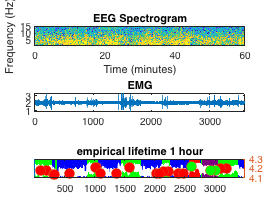

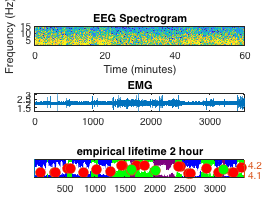

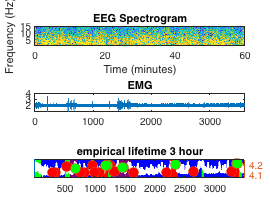

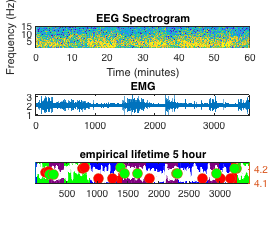

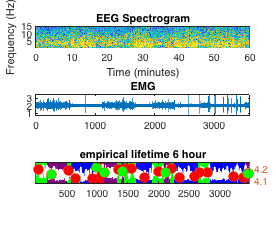

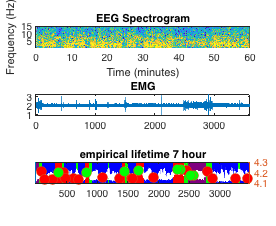

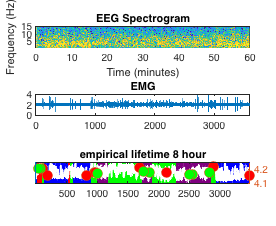


Fs = 200; % 
tWindow = 10; % The window must be long enough to get 64ms of the signal
NWindow = Fs*tWindow; % Number of elements the window must have
window = hamming(NWindow); % Window used in the spectrogram
NFFT = NWindow;
NOverlap = NWindow*0.99; % We want a 99% overlap,

for i=1:12
    this_plot_points=find(t>=3600*(i-1) & t<=3600*i);
    this_plot_points_EEG=find(EEGtimedark>=3600*(i-1) & EEGtimedark<=3600*i);
    this_plot_points_EMG=find(EMGtimedark>=3600*(i-1) & EMGtimedark<=3600*i);
    EMGtime_plot=EMGtimedark(this_plot_points_EMG);
    EMGtime_plot=EMGtime_plot-EMGtime_plot(1);

    this_plot_median_points_1=median_time_1(find(t1>=3600*(i-1) & t1<=3600*i));
    this_plot_median_points_2=median_time_2(find(t2>=3600*(i-1) & t2<=3600*i));
    this_plot_median_points_3=median_time_3(find(t3>=3600*(i-1) & t3<=3600*i));
    this_plot_median_points_4=median_time_4(find(t4>=3600*(i-1) & t4<=3600*i));

    this_plot_median_points_1out=median_time_1out(find(t1out>=3600*(i-1) & t1out<=3600*i));
    this_plot_median_points_2out=median_time_2out(find(t2out>=3600*(i-1) & t2out<=3600*i));
    this_plot_median_points_3out=median_time_3out(find(t3out>=3600*(i-1) & t3out<=3600*i));
    this_plot_median_points_4out=median_time_4out(find(t4out>=3600*(i-1) & t4out<=3600*i));
    
    figure1=figure;
    figure1.Position=[10 10 1100 900];

    subplot1=subplot(3,1,1,'Parent',figure1);
    hold(subplot1,'on')
    spectrogram(EEGdata_all_dark(this_plot_points_EEG), window, NOverlap, NFFT, Fs,'yaxis');
    ylim([1,15])
    caxis([-40 -10])
    colorbar('off')
    box(subplot1,'on')
    title('EEG Spectrogram')
    hold(subplot1,'off')

    subplot2=subplot(3,1,2,'Parent',figure1);
    hold(subplot2,'on')
    plot(EMGtime_plot,EMGdata_all_dark(this_plot_points_EMG))
    xlim([0 3600])
    box(subplot2,'on')
    title('EMG')
    hold(subplot2,'off')

    subplot3=subplot(3,1,3,'Parent',figure1);
    yyaxis left
    imagesc(states_for_time_all_dark(this_plot_points)')
    caxis([1 4])
    colormap(subplot3,[0 1 0;0 0 1;1 0 0;.5 0 .5])
    colorbar('off')
    set(gca, 'YTick', []);
    title(['empirical lifetime ',num2str(i),' hour' ])
    
    yyaxis right
    plot(tau_empTrunc_all_darkonly(this_plot_points),'LineWidth',2,'Color','white')
    
    
    hold(subplot3,'on')
    yyaxis right
    plot(this_plot_median_points_1-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_1)','o','MarkerSize',10,'MarkerFaceColor','Red')
    plot(this_plot_median_points_2-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_2)','o','MarkerSize',10,'MarkerFaceColor','Red')
    plot(this_plot_median_points_3-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_3)','o','MarkerSize',10,'MarkerFaceColor','Green')
    plot(this_plot_median_points_4-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_4)','o','MarkerSize',10,'MarkerFaceColor','Green')

    plot(this_plot_median_points_1out-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_1out)','o','MarkerSize',10,'MarkerFaceColor','Black')
    plot(this_plot_median_points_2out-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_2out)','o','MarkerSize',10,'MarkerFaceColor','Black')
    plot(this_plot_median_points_3out-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_3out)','o','MarkerSize',10,'MarkerFaceColor','Black')
    plot(this_plot_median_points_4out-this_plot_points(1)+1,tau_empTrunc_all_darkonly(this_plot_median_points_4out)','o','MarkerSize',10,'MarkerFaceColor','Black')
    hold(subplot3,'off')
    
    figurename=['median_ploted_',num2str(i),'.png'];
    saveas(figure1, figurename)
    
    
    
    
    
end